# Localization 2d

Simulation of a robot moving in a 2d plane. Measurements are taken by beacons ( which transmit the range back to the robot ).

Date Started : 13 Dec. 2023 , 4: 30 PM

Author : Giorgio Ridolfi

## Sources

1) [https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine](https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine)

2) [https://undocumentedmatlab.com/](https://undocumentedmatlab.com/)

3) Ristic, Branko, Sanjeev Arulampalam, and Neil Gordon. Beyond the Kalman filter: Particle filters for tracking applications. Artech house, 2003.

4) [https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8](https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8)

## System Info

close all
clc
display("OS : " + computer("arch") + ", " + feature('GetOS') )

    "OS : win64, Microsoft Windows 11 Pro N"



display("Processor : " + feature('GetCPU') + ", " + feature('numCores') )

    "Processor : Intel(R) Core(TM) i5-8600K CPU @ 3.60GHz, 6"



% GPU = gpuDevice
clear all


## Generation of poses

We first generate a set of desired poses. From these, we create noisy system inputs to feed our robot by adding gaussian noise to the true inputs. Then we calculate the robot's actual poses

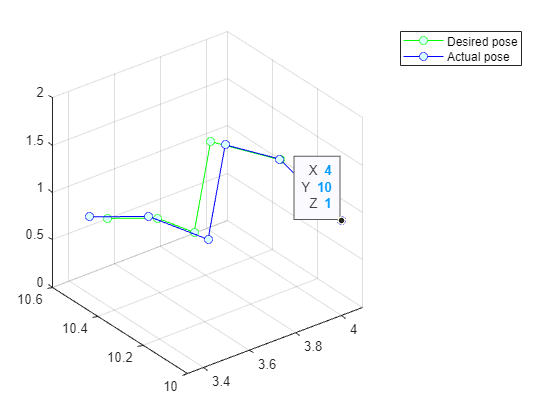

N =5;
pose = zeros(3,N+1); % x_meters y_meters theta_radians
pose_0 = [ randi(10) ; randi(10) ; randi([0 360])  ];
pose(:,1) = pose_0;
u = zeros(3,N); 
real_pose = zeros(3,N+1); 
real_pose( : , 1 ) = pose_0;

% Random walk params
stdx = 0.22;
stdy = 0.23;
th_max = 2; % Degrees
stdtr = 0.04;
stdrot = 0.01745329251*0.03; 


for i = 1 : N
 x_incr = stdx*randn() ;
 y_incr = stdy*randn();
 th_incr = 0.01745329251*randi( [-th_max th_max] ) ;
 
 pose(:,i+1) = pose(:,i) +  [ x_incr ; y_incr ; th_incr ] ; 

 transl = sqrt( x_incr*x_incr + y_incr*y_incr ) ;
 rot1 = atan2(y_incr,x_incr) ;
 rot2 = pose(3,i+1) - pose(3,i) - rot1 ;
 
 u(:,i) = [ transl + stdtr*randn()  ; rot1 + stdrot*randn() ; rot2 + stdrot*randn() ];


 real_pose(3,i+1) = real_pose(3,i) + u(2,i);
 real_pose(1,i+1) = real_pose(1,i) + u(1,i)*cos( u(2,i) );
 real_pose(2,i+1) = real_pose(2,i) + u(1,i)*sin(u(2,i) );
 real_pose(3,i+1) = real_pose(3,i) + u(3,i) ;

end


z = ones(1,N+1);
figure
plot3( pose(1,:), pose(2,:) , z , '-o','Color','green','MarkerSize',6,'MarkerFaceColor','#D9FFFF')
hold on
grid on
plot3(real_pose(1,:) , real_pose(2,:) , z , '-o','Color','b','MarkerSize',6, 'MarkerFaceColor','#D9FFFF' )
legend("Desired pose" , "Actual pose")


clear pose x_incr y_incr th_incr transl rot1 rot2 z



## Creation of arena 

% dim_bound = 100;
% x_bounds = [1:1:dim_bound];
% y_bounds = [1:1:dim_bound];
% 
% z_surf = ones(dim_bound);
% 
% % z_surf = meshgrid(x_bounds , y_bounds);
% % z_surf = exp(-0.001*(z_surf - 0.5*dim_bound*ones(dim_bound)).^2) ;
% 
% figure
% surf(x_bounds,y_bounds,z_surf,"FaceColor",[195 250 255]/255 )
% 
% hold on
% 

## Creation of landmarks

% num_landmarks = 3;
% coord_landmarks = zeros(3, num_landmarks);
% for i = 1 : num_landmarks
%     x_lm = randi(dim_bound);
%     y_lm = randi(dim_bound) ;
%     coord_landmarks(:,i) = [x_bounds(x_lm) ; y_bounds(y_lm) ; z_surf(y_lm , x_lm)];
% end
% scatter3(coord_landmarks(1,:) , coord_landmarks(2,:) , coord_landmarks(3,:) , 80 , 'red' , 'filled' , 'v' , 'MarkerEdgeColor','flat' , 'MarkerFaceColor','flat') 
% 
% clear x_lm y_lm 
% coord_landmarks

## SLAM

% % Assume that the location of the landmarks is not known a priori. This is
% % coded in the form of a huge initial covariance
% 

## APPENDIX : Functions

% function [ranges_out , bearings_out ] = hRadar(x_in , lm_coords)
% % Usage : pass an xyz position and obtain a number of measurements
% % corresponding to the 2*length(lm_coords) , representing range and bearing
% % of every landmark wrt to current robot position
% sizes_lm = size(lm_coords);
% num_lm = sizes_lm(1);
% 
% 
% 
% end
